clear;clc;close all

colorlist1 = [
    255, 130, 131;  %1 肉粉
    249, 204, 82;   %2 黄
    247,170,88;     %3 橙
    13, 137, 138;   %4 叶绿
    84, 148, 206;   %5 蓝灰
    30,70,110       %6 蓝
    ]./255;

filename = 'G:\1防火课题\向量式有限元\与试验框架对比.xlsx';
datatable = readtable(filename,'Sheet','ehr','VariableNamingRule','preserve');
markers = {'o', 'square', 'diamond', 'v', '^', '+'};

xdata1 = datatable.testw4(:);
ydata1 = datatable.tw4(:);
xdata2 = datatable.testu2(:);
ydata2 = datatable.tu2(:);
xdata3 = datatable.liuw4(:);
ydata3 = datatable.lw4(:);
xdata4 = datatable.liuu2(:);
ydata4 = datatable.lu2(:);
xdata5 = datatable.chuw4(:);
ydata5 = datatable.cw4(:);
xdata6 = datatable.chuu2(:);
ydata6 = datatable.cu2(:);

figure;
hold on;
plot(xdata2, ydata2, 'o', 'DisplayName', 'u_2: Fire test', ...
    'MarkerEdgeColor', colorlist1(1,:), 'MarkerFaceColor', colorlist1(1,:), 'MarkerSize',6);
plot(xdata1, ydata1, '^', 'DisplayName', 'u_4: Fire test', ...
    'MarkerEdgeColor', colorlist1(5,:), 'MarkerFaceColor', colorlist1(5,:), 'MarkerSize',6);
plot(xdata4, ydata4, 'o', 'DisplayName', 'u_2: K.H.Lien et al.(2010)', ...
    'MarkerEdgeColor', colorlist1(1,:), 'MarkerFaceColor', 'none', 'MarkerSize',6, 'LineWidth', 1.5);
plot(xdata3, ydata3, '^', 'DisplayName', 'u_4: K.H.Lien et al.(2010)', ...
    'MarkerEdgeColor', colorlist1(5,:), 'MarkerFaceColor', 'none', 'MarkerSize',6, 'LineWidth', 1.5);
plot(xdata6, ydata6, 'Color', colorlist1(1, :), 'LineWidth', 1.5, 'DisplayName', 'u_2: Proposed model');
plot(xdata5, ydata5, 'Color', colorlist1(5, :), 'LineWidth', 1.5, 'DisplayName', 'u_4: Proposed model');

ax = gca;
ax.XLim = [0, 600];
ax.YLim = [0, 50];
ax.LineWidth = 1.1;
ax.TickDir = 'in';
ax.TickLength = [.01 .01];
ax.XTick = 0:100:600;
ax.YTick = 0:10:50;
ax.FontSize = 14;
ax.FontName = 'Cambria'

ax =   Axes - 属性:

             XLim: [0 600]
             YLim: [0 50]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  显示 所有属性


ax.XGrid = "on";
ax.YGrid = "on";
ax.GridLineStyle = '--';
ax.LooseInset = [0, 0, 0, 0]; %调整边缘空间
set(ax, 'GridColor', [0, 0, 0]);
ax.GridAlpha = 0.3

ax =   Axes - 属性:

             XLim: [0 600]
             YLim: [0 50]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '--'
         Position: [0.0471 0.0676 0.9261 0.9062]
            Units: 'normalized'

  显示 所有属性


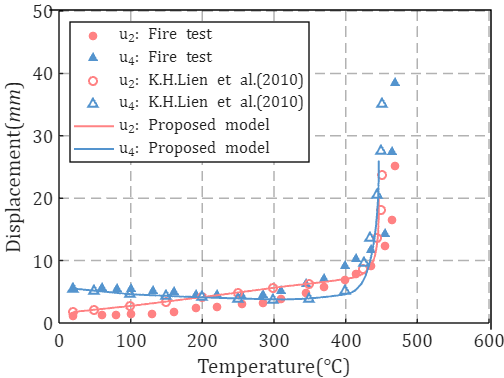


xlabel('Temperature(℃)', 'FontName', 'Cambria', 'FontSize', 16);
ylabel('Displacement({\itmm})', 'FontName', 'Cambria', 'FontSize', 16);

lgd=legend('show');
lgd.NumColumns=1;
lgd.FontName = 'Cambria';
lgd.FontSize=13;
lgd.Location='northwest';

box off;
ax1 = axes('Position',get(ax,'Position'),'XAxisLocation','top',...
    'YAxisLocation','right','Color','none','XColor','k','YColor','k');  % 设置坐标区
ax1.LineWidth = 1.1;
ax1.LooseInset = [0, 0, 0, 0]; %调整边缘空间
set(ax1,'XTick', [],'YTick', []);   % 去掉xy轴刻度

figw = 3.5 * 2.54;
figh = 2.5 * 2.54;
figureUnits = 'centimeters';
fig = gcf;
set(gcf, 'Theme', 'light');
set(gcf, 'color', 'w');
fig.PaperUnits = figureUnits;
hold off

fileout = 'G:\1防火课题\向量式有限元\ehr.jpg';
print(fig, fileout, '-djpeg', '-r400');